
cd /Users/serg/github_projects/QASS_SVM/data
load iris.mat
blackColor = [0 0 0];
rng('default')
rng(1234)

tstart = tic;    
simplex=[];
run=[1:100];

for r=run,
    [gam ,sig2 , cost] = tunelssvm({ Xtrain , Ytrain , 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'misclass'});
    simplex=[simplex; gam ,sig2 , cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2203.2372
                                          [sig2]        1.1334
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2203.2372      1.1333969

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     4.000000e-02     8.8977        0.1252      initial 
     2           5     4.000000e-02     8.8977        0.1252      contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=7315.005001   1.133397, F(X)=4.000000e-02 

Obtained hyper-

tend = toc;

tend/60

ans = 1.8533

tstart = tic;    
grid=[];
run=[1:100];

for r=run,
    [gam ,sig2 , cost] = tunelssvm({ Xtrain , Ytrain , 'c', [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm',{10, 'misclass'});
    grid=[grid; gam ,sig2 , cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         610.4708
                                          [sig2]        0.072627
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   30.3936   0.00596158
    cost of starting values:           0.07
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         30.3935528      90601.9039
                          [sig2]        0.0059616     0.88478
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=4.7476     -3.4558 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.2048, X=5.7639     -2.8088 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 318.6012    0.06027803

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.8658
                                          [sig2]        0.084075
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.29204   0.0069013
    cost of starting values:           0.11
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.2920392      870.5567
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=2.7691      -2.476 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7408, X=4.3794     -1.8146 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 79.7909      0.16291

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.1283
                                          [sig2]        0.028034
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.10596   0.0023012
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.105964      315.8742
                          [sig2]        0.0

grain = 7

FIRST ITERATION:
   X=-2.2447     -1.9077 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.375, X=-0.97565     -1.3782 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.37695     0.25202

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         21457.0034
                                          [sig2]        0.098519
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1068.2813   0.0080869167
    cost of starting values:           0.06
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         1068.281293      3184501.6527
                          

grain = 7

FIRST ITERATION:
   X=9.6405     -2.3175 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.4121, X=11.0254     -2.04152 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 61412.4964     0.129831775

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.044413
                                          [sig2]        0.66222
                                          F(X)=         0.02
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0022112    0.054359
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0022112      6.5914
                          [sig2] 

grain = 7

FIRST ITERATION:
   X=-3.4476     -1.2455 ,F(X)=0.04;
ITERATION: 2
  dF=0.02, dX=0.48226, X=-3.3363    -0.77624 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 0.035569     0.46013

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.67116
                                          [sig2]        8.0351
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.033415     0.65956
    cost of starting values:           0.06
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0334152      99.6094
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=3.2679      3.7505 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.2594, X=4.3818      4.3382 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 79.9832      76.5666

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.2303
                                          [sig2]        0.13488
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.061255    0.011071
    cost of starting values:           0.28
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.06125515       182.599
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.7927     -1.1701 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.1972, X=-2.4879   -0.012283 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.08308     0.98779

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.5439
                                          [sig2]        0.17971
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.076866    0.014751
    cost of starting values:           0.19
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.07686631      229.1353
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.5657     0.78358 ,F(X)=0.03;
ITERATION: 2
  dF=0.01, dX=0.87947, X=-3.0616     0.05724 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 0.046814      1.0589

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         16.6249
                                          [sig2]        0.013765
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.8277   0.0011299
    cost of starting values:           0.21
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.82770281      2467.3473
                          [sig2]  

grain = 7

FIRST ITERATION:
   X=1.1442     -4.2856 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.5815, X=2.7257     -4.2854 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 15.2673    0.0137676

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.4528
                                          [sig2]        0.034092
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.022543   0.0027984
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.0225434      67.2009
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.459      -1.712 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5803, X=-0.9792     -1.1575 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.37561     0.31428

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.03713
                                          [sig2]        0.42721
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0018486    0.035067
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0018486      5.5106
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.2933     -2.5172 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.1, X=-1.5299     -3.3091 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.03713     0.42721

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.4735
                                          [sig2]        2.0245
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.073364     0.16618
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.07336355      218.6937
                          [sig2]        0.16

grain = 7

FIRST ITERATION:
   X=-2.6123     -1.7947 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.6322, X=-1.013     -1.4689 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.36314     0.23018

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.91939
                                          [sig2]        0.22501
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.045774     0.01847
    cost of starting values:           0.27
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.04577392      136.4501
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-1.7507     -3.1583 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4422, X=-0.50416      -2.433 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.60401     0.08777

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         371.3322
                                          [sig2]        1.6654
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   18.4875     0.136708
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         18.4875394      55110.5782
                          [sig2]    

grain = 7

FIRST ITERATION:
   X=2.9171     -1.9899 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5147, X=4.4318     -1.9799 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 84.0785     0.138082

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.62814
                                          [sig2]        0.25504
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.031273    0.020935
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0312735      93.2248
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.1317     -1.3663 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=1.3604, X=-3.2656    -0.61469 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.038176     0.54081

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.327
                                          [sig2]        0.14576
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.21543    0.011965
    cost of starting values:           0.12
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.2154281       642.182
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-1.5351     -2.7591 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4791, X=-0.19548     -2.1321 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.82244     0.11859

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.058801
                                          [sig2]        0.85305
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0029275    0.070022
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0029275      8.7269
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-3.1669    -0.99227 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=0.7412, X=-2.9225    -0.29253 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.053799     0.74637

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.5452
                                          [sig2]        2.5623
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.076933     0.21033
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.07693302      229.3341
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=-2.5648     -1.5591 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=1.0682, X=-3.1342    -0.65536 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.043532     0.51926

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         10025.3941
                                          [sig2]        0.40345
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   499.135    0.03311719
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         499.13497966      1487900.4042
                         

grain = 7

FIRST ITERATION:
   X=8.8795     -0.9077 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.5675, X=10.4456    -0.840395 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 34394.2633     0.431540198

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         29.6003
                                          [sig2]        0.045295
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.4737   0.0037181
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         1.4737116      4393.0723
                          [sig2] 

grain = 7

FIRST ITERATION:
   X=3.0545     -3.0946 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.8144, X=4.7482      -3.745 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 115.3817    0.02363514

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.1104
                                          [sig2]        2.0624
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0054965     0.16929
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00549652      16.3849
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.537     -1.7761 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=1.0405, X=-2.9803    -0.83483 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.05078     0.43395

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         17102.2913
                                          [sig2]        0.42831
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   851.4729    0.03515751
    cost of starting values:           0.06
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         851.47294416      2538205.0736
                          

grain = 7

FIRST ITERATION:
   X=8.0803    -0.84792 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7949, X=9.8665      -1.025 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 19273.0547     0.358787429

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.26579
                                          [sig2]        0.03649
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.013233   0.0029953
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0132327      39.4462
                          [sig2]    

grain = 7

FIRST ITERATION:
   X=-2.9917    -0.81071 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.99801, X=-2.7616     -1.7818 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.063194     0.16833

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         43274.4563
                                          [sig2]        0.62354
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2154.5083    0.051183629
    cost of starting values:           0.07
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         2154.5083149      6422498.7696
                        

grain = 7

FIRST ITERATION:
   X=10.342    -0.472336 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.5525, X=11.8922    -0.386718 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 146116.2114     0.6792823532

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3846.9284
                                          [sig2]        1.3916
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   191.5273      0.114233
    cost of starting values:           0.03
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         191.5272857      570934.7921
                      

grain = 7

FIRST ITERATION:
   X=11.9217     0.330485 ,F(X)=0.02;
ITERATION: 2
  dF=0, dX=1.939, X=13.8543      0.48767 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 1039518.2161      1.6285169302

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         107.6051
                                          [sig2]        0.15197
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.3573    0.012475
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         5.35734484      15970.0199
                          

grain = 7

FIRST ITERATION:
   X=4.3451     -1.8841 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.8174, X=6.1382     -1.5877 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 463.2065      0.204404

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.58922
                                          [sig2]        0.37688
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.029335    0.030936
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0293354      87.4475
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.1956     -2.6425 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5203, X=-0.7343     -2.2232 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.47984     0.10826

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         41.7756
                                          [sig2]        0.085846
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.0799   0.0070467
    cost of starting values:           0.06
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         2.0798836      6200.0458
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=3.399     -2.4552 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.4936, X=4.8142     -1.9779 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 123.2506     0.1383644

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         46.5181
                                          [sig2]        0.60395
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.316    0.049576
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         2.3159984      6903.8939
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=0.83984     -3.0043 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5096, X=2.3237      -3.282 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 10.2134    0.0375526

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         16.7493
                                          [sig2]        0.32004
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.8339    0.026271
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.83389895      2485.8177
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-0.18164     -3.6393 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4932, X=1.3112      -3.609 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 3.7107     0.02708

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.8684
                                          [sig2]        0.094085
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.24238   0.0077229
    cost of starting values:           0.12
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.242385      722.5395
                          [sig2]        0.0077

grain = 7

FIRST ITERATION:
   X=-1.4172     -2.3636 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5606, X=-0.30724     -1.2665 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.73547     0.28181

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         12.1949
                                          [sig2]        0.38688
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.60715    0.031757
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.60714679      1809.8791
                          [sig2]      

grain = 7

FIRST ITERATION:
   X=-0.49898     -3.4496 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5147, X=1.0157     -3.4396 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 2.7612    0.032076

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.5135
                                          [sig2]        0.11804
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.12514   0.0096897
    cost of starting values:           0.22
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.1251412      373.0405
                          [sig2]        0.0

grain = 7

FIRST ITERATION:
   X=-2.0783     -2.1367 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.6121, X=-0.54803     -1.6297 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.57809     0.19599

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.65382
                                          [sig2]        0.046061
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.032552   0.0037809
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0325518      97.0355
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-2.0916     -2.2445 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.784, X=-0.72136     -3.3869 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.48609    0.033812

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.2337
                                          [sig2]        0.21507
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.11121    0.017654
    cost of starting values:           0.11
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.1112116       331.517
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.1963     -1.5368 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4427, X=-0.84773     -1.0242 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.42839     0.35907

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.1007
                                          [sig2]        0.18983
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.15438    0.015582
    cost of starting values:           0.1
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.1543758      460.1877
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-1.8684      -2.495 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5606, X=-0.75838     -1.3979 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.46843     0.24711

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.51017
                                          [sig2]        0.021139
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0254   0.0017352
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0253999      75.7162
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-1.0063     -3.8566 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.242, X=0.2066     -4.1235 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 1.2295    0.016188

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.017
                                          [sig2]        2.5119
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.10042     0.20619
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.1004197       299.347
                          [sig2]        0.20618

grain = 7

FIRST ITERATION:
   X=-2.2984     0.92102 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0, X=-2.2984     0.92102 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.10042      2.5119

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.6393
                                          [sig2]        0.21331
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.1314     0.01751
    cost of starting values:           0.12
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.1314042      391.7103
                          [sig2]        0.01751 

grain = 7

FIRST ITERATION:
   X=-2.0295     -2.3783 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.448, X=-1.2521     -1.1567 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.28592     0.31453

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.2275
                                          [sig2]        12.8372
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.061112      1.0537
    cost of starting values:           0.05
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.06111227      182.1731
                          [sig2]        1

grain = 7

FIRST ITERATION:
   X=2.5383      3.3857 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.7761, X=4.1349      4.1637 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 62.4816      64.3099

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.11309
                                          [sig2]        2.8574
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0056304     0.23455
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00563043      16.7841
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.5129     -1.4501 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=1.3091, X=-3.336    -0.43208 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.035579     0.64916

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.3641
                                          [sig2]        0.40556
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.36664     0.03329
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.36663689      1092.9292
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=-1.0034     -3.4025 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5147, X=0.51127     -3.3925 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 1.6674    0.033625

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.4712
                                          [sig2]        0.13296
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.073248    0.010914
    cost of starting values:           0.26
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.07324803      218.3493
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.6139     -1.1844 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=2.1101, X=-0.72646     -2.1279 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.48362     0.11909

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.3005
                                          [sig2]        0.028563
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.2639   0.0023446
    cost of starting values:           0.23
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.263898      786.6689
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-1.3322     -3.5556 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.626, X=0.14019     -2.8658 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 1.1505     0.05694

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         20166.3045
                                          [sig2]        5.0383
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1004.0212     0.41356925
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1004.0211798      2992944.9552
                          [si

grain = 7

FIRST ITERATION:
   X=12.2451     0.783736 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.8891, X=14.0999     0.425376 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 1328999.4105      1.5301649359

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.057199
                                          [sig2]        0.94721
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0028478    0.077751
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0028478      8.4891
                          [

grain = 7

FIRST ITERATION:
   X=-3.1945    -0.88757 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.50642, X=-3.3205     -1.3781 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.036134     0.25206

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         50.4824
                                          [sig2]        0.030902
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.5134   0.0025366
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         2.5133685      7492.2458
                          [sig2]      

grain = 7

FIRST ITERATION:
   X=0.92162     -3.4769 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5562, X=2.2705     -2.7008 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 9.684    0.067153

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         34.7831
                                          [sig2]        0.091304
                                          F(X)=         0.02
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.7317   0.0074947
    cost of starting values:           0.07
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1.7317473      5162.2658
                          [sig2]        0.0

grain = 7

FIRST ITERATION:
   X=4.5491     -2.3936 ,F(X)=0.02;
ITERATION: 2
  dF=0, dX=1.0068, X=5.3111     -1.7356 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 202.5782     0.1763017

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.5066
                                          [sig2]        0.094952
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.1248   0.0077942
    cost of starting values:           0.2
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.1247973      372.0156
                          [sig2]        0.007

grain = 7

FIRST ITERATION:
   X=-2.0811     -3.1877 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=0.397, X=-1.7153      -3.342 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.17992    0.035368

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         11.9184
                                          [sig2]        0.033594
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.59338   0.0027576
    cost of starting values:           0.15
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.59338263      1768.8487
                          [sig2]    

grain = 7

FIRST ITERATION:
   X=-0.52192     -3.3934 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.787, X=1.2141     -2.9698 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 3.3673    0.051314

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         114.5696
                                          [sig2]        0.18925
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.7041    0.015534
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         5.70408471      17003.6369
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=1.7412     -3.3314 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7103, X=3.3595     -3.8846 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 28.7757    0.0205569

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.14288
                                          [sig2]        0.41185
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0071135    0.033807
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00711346      21.2049
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.2791     -1.7204 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5245, X=-2.2503    -0.19625 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.10537     0.82181

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.846
                                          [sig2]        0.092811
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.091905   0.0076184
    cost of starting values:           0.24
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.09190487      273.9646
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.387     -3.2105 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.6671, X=-0.8182     -2.6464 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.44122    0.070903

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.37813
                                          [sig2]        0.10062
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.018826   0.0082597
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.0188261      56.1198
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-1.3058      -3.963 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.28162, X=-1.0327     -4.0317 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.35603    0.017744

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.86329
                                          [sig2]        0.013091
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.042981   0.0010746
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.04298053      128.1231
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=0.85299     -4.3358 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.2958, X=2.1438     -4.2212 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 8.5315     0.01468

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         101.5929
                                          [sig2]        0.16264
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.058     0.01335
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         5.0580111      15077.7186
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=2.9543     -2.6496 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.6395, X=4.5938     -2.6471 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 98.8738    0.0708553

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.042022
                                          [sig2]        0.399
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0020922    0.032752
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0020922      6.2366
                          [sig2]        0.0

grain = 7

FIRST ITERATION:
   X=1.8304     -3.4188 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=2.0299, X=3.8408     -3.6999 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 46.5608    0.0247257

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.7934
                                          [sig2]        0.11622
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.08929   0.0095401
    cost of starting values:           0.21
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.08929024      266.1704
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.4159     -1.3189 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=0.90606, X=-3.198    -0.86157 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.040843      0.4225

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.076063
                                          [sig2]        1.4468
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.003787     0.11876
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.00378697      11.2888
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-2.9095     -1.2973 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0, X=-2.9095     -1.2973 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.054502     0.27327

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.289
                                          [sig2]        0.1432
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.26332    0.011755
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.2633219      784.9515
                          [sig2]        0.011755

grain = 7

FIRST ITERATION:
   X=-1.3344     -2.7768 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4852, X=0.057214      -2.258 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 1.0589     0.10456

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4808.6165
                                          [sig2]        0.036182
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   239.4069   0.002970003
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         239.4069164      713661.9596
                          [sig

grain = 7

FIRST ITERATION:
   X=5.4782     -3.3192 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.6019, X=7.027     -2.9104 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 1126.6844    0.054452541

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.026
                                          [sig2]        2.5444
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.051082     0.20886
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.05108175      152.2725
                          [sig2]        0.2

grain = 7

FIRST ITERATION:
   X=-2.9743    -0.73275 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.53145, X=-3.0253    -0.20375 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.048544     0.81566

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.063196
                                          [sig2]        1.5702
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0031463     0.12889
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0031463      9.3791
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-3.0949    -0.38212 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.33924, X=-3.1826    -0.70982 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.041478     0.49173

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         65.0428
                                          [sig2]        0.77523
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   3.2383    0.063635
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         3.2382915      9653.2109
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=1.175     -2.7546 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5147, X=2.6897     -2.7446 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 14.7273    0.0642745

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.57322
                                          [sig2]        3.0937
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.028539     0.25395
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0285389      85.0731
                          [sig2]        0.25

grain = 7

FIRST ITERATION:
   X=-2.2232     -1.3706 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.7558, X=-0.47403      -1.524 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.62249     0.21783

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.3423
                                          [sig2]        2.263
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.066831     0.18576
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.06683125      199.2211
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.7056     -1.6833 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=0.63721, X=-3.2322     -1.3246 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.039469     0.26591

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.98861
                                          [sig2]        0.31747
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.04922     0.02606
    cost of starting values:           0.22
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.04921994      146.7226
                          [sig2]   

grain = 7

FIRST ITERATION:
   X=-3.0115     -1.1474 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5894, X=-2.3702     0.30687 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.093465      1.3592

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.29164
                                          [sig2]        2.7346
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.01452     0.22447
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0145197      43.2827
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-2.8989      -1.494 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=2.0291, X=-0.86985     -1.4944 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.41901     0.22438

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.9522
                                          [sig2]        0.020795
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.097194    0.001707
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.09719428      289.7321
                          [sig2]      

grain = 7

FIRST ITERATION:
   X=-0.99771      -3.873 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.29502, X=-0.7118     -3.9458 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.49076    0.019336

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.0359
                                          [sig2]        0.059167
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.10136   0.0048567
    cost of starting values:           0.31
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.10136        302.15
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.2891     -1.9941 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.2222, X=-1.2983     -1.2783 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.27299      0.2785

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.88695
                                          [sig2]        0.14682
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.044158    0.012052
    cost of starting values:           0.32
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0441585      131.6346
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-3.12     -1.0852 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=0.55778, X=-2.7899     -1.5349 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.061427     0.21548

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.087535
                                          [sig2]        1.1269
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0043581    0.092504
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00435811      12.9914
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-2.769     -1.5472 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.6113, X=-1.1668     -1.3766 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.31136     0.25243

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         213616.7471
                                          [sig2]        1.4655
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   10635.3516      0.12029783
    cost of starting values:           0.07
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         10635.35159      31703536.2673
                         

grain = 7

FIRST ITERATION:
   X=13.2719     0.382215 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.6727, X=14.9154     0.693753 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 3003687.2224      2.0012116186

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.0218
                                          [sig2]        1.6738
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.050874      0.1374
    cost of starting values:           0.05
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.05087397      151.6532
                          [s

grain = 7

FIRST ITERATION:
   X=-2.9784     -1.1516 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4125, X=-1.5946    -0.86838 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.20299     0.41963

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         44.0324
                                          [sig2]        0.057414
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.1922   0.0047128
    cost of starting values:           0.08
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         2.1922461      6534.9936
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=3.4516     -3.6908 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7427, X=5.1304     -3.2232 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 169.0874    0.03982699

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         311.9336
                                          [sig2]        1.0072
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   15.5303    0.0826783
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         15.5302586      46295.0485
                          [sig2]    

grain = 7

FIRST ITERATION:
   X=2.7428     -2.4928 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5096, X=4.2267     -2.7706 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 68.4875    0.0626272

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         8.3388
                                          [sig2]        0.39658
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.41517    0.032553
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.41516616      1237.5929
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-0.87908     -3.4249 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5147, X=0.63558     -3.4149 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 1.8881     0.03288

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         38.2594
                                          [sig2]        0.77982
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.9048    0.064012
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         1.9048212      5678.1921
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=0.64439     -2.7487 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.7897, X=2.4316     -2.6555 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 11.3772    0.0702625

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         489.3052
                                          [sig2]        1.4557
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   24.3611      0.11949
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         24.3610695      72619.3247
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=3.193     -2.1245 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5689, X=4.7613     -2.0822 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 116.9026     0.1246606

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.20024
                                          [sig2]        0.11676
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0099692   0.0095846
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00996918      29.7177
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-3.2749    -0.48093 ,F(X)=0.03;
ITERATION: 2
  dF=0.01, dX=0.5047, X=-3.096    -0.95284 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 0.045231     0.38564

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.4731
                                          [sig2]        0.034604
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.023554   0.0028405
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.0235541      70.2138
                          [sig2]      

grain = 7

FIRST ITERATION:
   X=-1.0818     -3.3638 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.0975, X=-0.29067     -4.1245 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.74776    0.016171

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.63204
                                          [sig2]        0.21702
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.031467    0.017814
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0314675      93.8032
                          [sig2]        

grain = 7

FIRST ITERATION:
   X=-2.1255     -2.3611 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.448, X=-1.348     -1.1394 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.25975        0.32

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.0271
                                          [sig2]        0.032095
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.15071   0.0026345
    cost of starting values:           0.3
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.1507093      449.2582
                          [sig2]        0.00263

grain = 7

FIRST ITERATION:
   X=-1.8924     -1.7724 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.8138, X=-0.71176     -3.1494 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.49078    0.042878

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.082844
                                          [sig2]        0.50953
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0041245    0.041825
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.00412454      12.2951
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=-2.8241     -1.5076 ,F(X)=0.04;
ITERATION: 2
  dF=0.01, dX=0.82364, X=-3.1441    -0.74866 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 0.043104       0.473

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.6012
                                          [sig2]        0.069211
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.17929   0.0056812
    cost of starting values:           0.21
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.1792909      534.4585
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-0.38541     -3.5039 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5644, X=0.86498     -2.5638 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 2.3749    0.077013

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.3758
                                          [sig2]        0.1968
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.068497    0.016155
    cost of starting values:           0.21
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.06849714      204.1871
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.681    -0.79222 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.2529, X=-2.2681     0.39072 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.10351       1.478

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.2476
                                          [sig2]        0.023864
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.012327   0.0019589
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0123272       36.747
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-3.0626     -2.0687 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5927, X=-2.0443     -0.8441 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.2476    0.023864

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         21210.5416
                                          [sig2]        0.98202
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1056.0107    0.080609238
    cost of starting values:           0.05
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1056.0106862      3147923.4895
                          [

grain = 7

FIRST ITERATION:
   X=6.9623    -0.85148 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5743, X=8.5254    -0.66471 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 5041.2322     0.51442303

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.8169
                                          [sig2]        0.43184
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.23982    0.035448
    cost of starting values:           0.05
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.2398213      714.8972
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-1.4279     -2.5064 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.6258, X=-0.099943     -1.5683 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.90489     0.20839

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.6467
                                          [sig2]        0.086239
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.13177   0.0070789
    cost of starting values:           0.22
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.1317699      392.8006
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-2.0267     -2.4506 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.4852, X=-1.0163     -1.3621 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.36192     0.25612

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.1394
                                          [sig2]        0.30781
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.05673    0.025267
    cost of starting values:           0.19
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.05672958      169.1085
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.8695    -0.34493 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.9523, X=-1.8126     -1.9864 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.16323     0.13718

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2203.1624
                                          [sig2]        1.5308
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   109.689     0.1256556
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         109.6889957      326978.2879
                          [sig2] 

grain = 7

FIRST ITERATION:
   X=4.6976     -2.0742 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=0.91723, X=5.541     -1.7136 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 254.9425     0.1802088

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.9686
                                          [sig2]        0.32253
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.1478    0.026475
    cost of starting values:           0.08
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.1477998      440.5849
                          [sig2]        0.

grain = 7

FIRST ITERATION:
   X=-1.9119     -2.7982 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5916, X=-0.3372     -2.5667 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.71377    0.076792

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6246.0425
                                          [sig2]        0.60906
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   310.9721    0.04999507
    cost of starting values:           0.03
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         310.9721463      926994.9033
                          [sig2

grain = 7

FIRST ITERATION:
   X=5.7397     -2.9958 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7698, X=7.4865     -3.2799 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 1783.8039    0.037630516

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         25.6926
                                          [sig2]        0.049683
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.2792   0.0040782
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.2791581      3813.1165
                          [sig2]     

grain = 7

FIRST ITERATION:
   X=0.2462     -4.6688 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=0, X=0.2462     -4.6688 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 1.2792   0.0093838

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         35.9945
                                          [sig2]        0.037352
                                          F(X)=         0.03
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.7921    0.003066
    cost of starting values:           0.09
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1.7920622      5342.0623
                          [sig2]        0.003066

grain = 7

FIRST ITERATION:
   X=1.9167     -3.2874 ,F(X)=0.03;
ITERATION: 2
  dF=0, dX=1.7413, X=3.6316     -3.5894 ,F(X)=0.03;
Obtained hyper-parameters: [gamma sig2]: 37.775    0.0276136

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.8348
                                          [sig2]        2.6513
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.091349     0.21763
    cost of starting values:           0.04
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.09134941      272.3088
                          [sig2]        0.2

grain = 7

FIRST ITERATION:
   X=-2.3931      -1.525 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.9009, X=-0.50545     -1.3008 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.60324     0.27231

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.057507
                                          [sig2]        0.26698
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.0028631    0.021915
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.0028631      8.5349
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-1.8558     -2.1539 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.0836, X=-1.4142     -3.1435 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.24311    0.043133

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.98085
                                          [sig2]        0.27883
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.048834    0.022888
    cost of starting values:           0.24
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.04883369      145.5712
                          [sig2]       

grain = 7

FIRST ITERATION:
   X=-3.0193     -1.2772 ,F(X)=0.04;
ITERATION: 2
  dF=0, dX=1.5454, X=-1.4768     -1.1836 ,F(X)=0.04;
Obtained hyper-parameters: [gamma sig2]: 0.22836     0.30618

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.0372
                                          [sig2]        1.5203
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.051637      0.1248
    cost of starting values:           0.06
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.05163717      153.9282
                          [sig2]        0

grain = 7

FIRST ITERATION:
   X=-2.9635     -1.2477 ,F(X)=0.04;
ITERATION: 2
  dF=0.02, dX=0.56153, X=-3.3071    -0.80363 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 0.036621      0.4477


tend = toc;

tend/60

ans = 3.6622

%Simplex
%Gamma
[f,xi] = ksdensity(log(simplex(:,1)));
fprintf('\n SIMPLEX: median gamma = %.2f  ', median(simplex(:,1)))


 SIMPLEX: median gamma = 7.49  

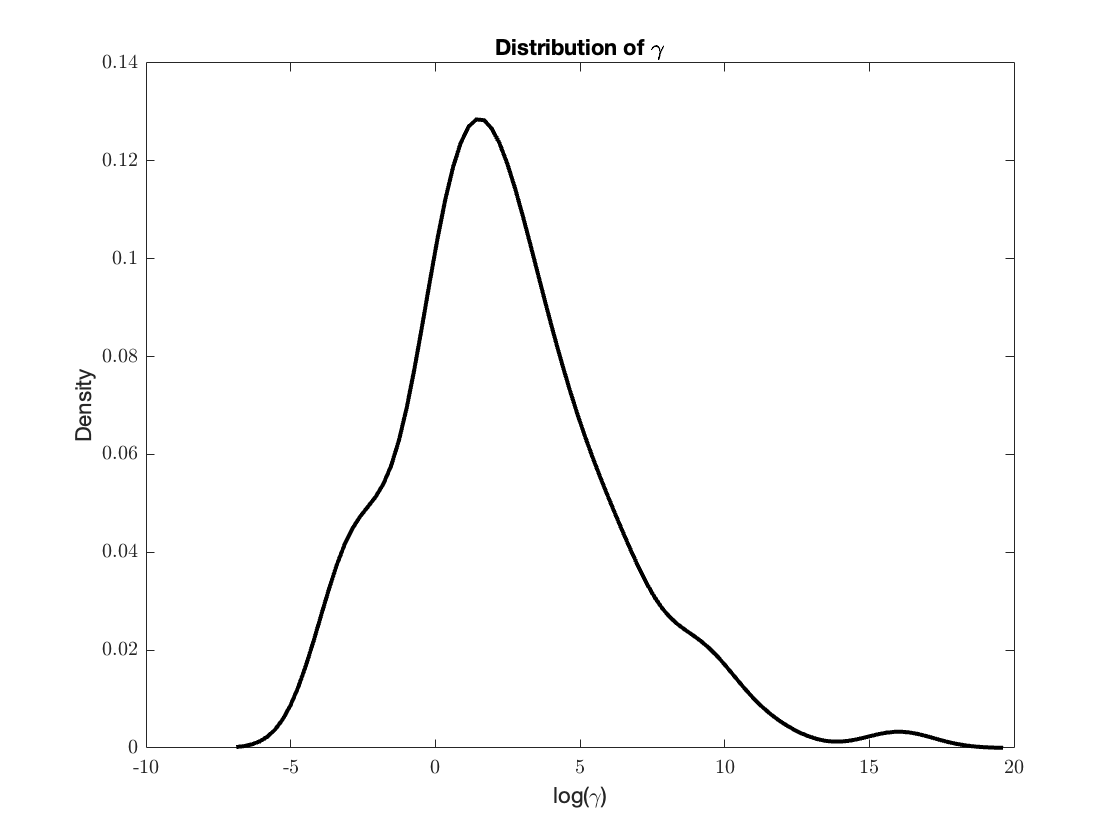


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\gamma)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_1.png','Resolution',300)



%Simplex
%Sigma
[f,xi] = ksdensity(log(simplex(:,2)));
fprintf('\n SIMPLEX: median sigma = %.2f  ', median(simplex(:,2)))


 SIMPLEX: median sigma = 0.33  

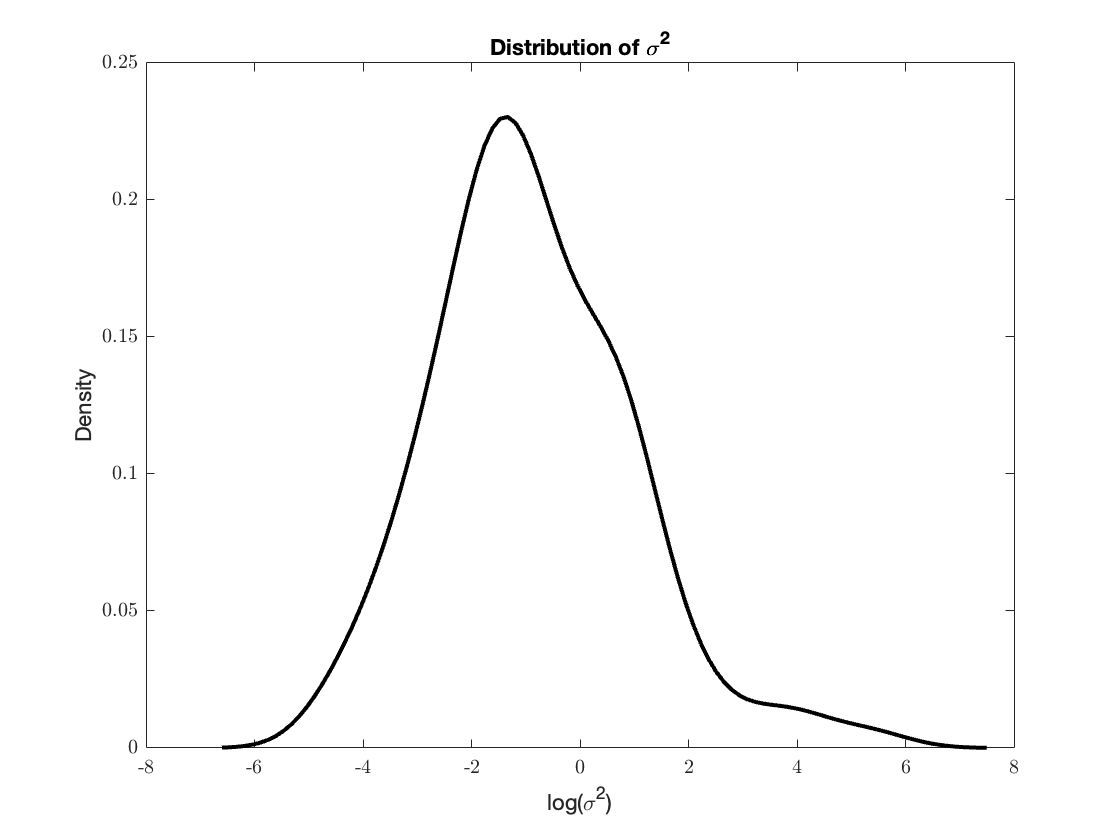



figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)

title('Distribution of \sigma^2');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\sigma^2)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_2.png','Resolution',300)



%Simplex
%Cost (error)
[f,xi] = ksdensity(log(simplex(:,3)));
fprintf('\n SIMPLEX: median cost = %.2f  ', median(simplex(:,3)))


 SIMPLEX: median cost = 0.04  

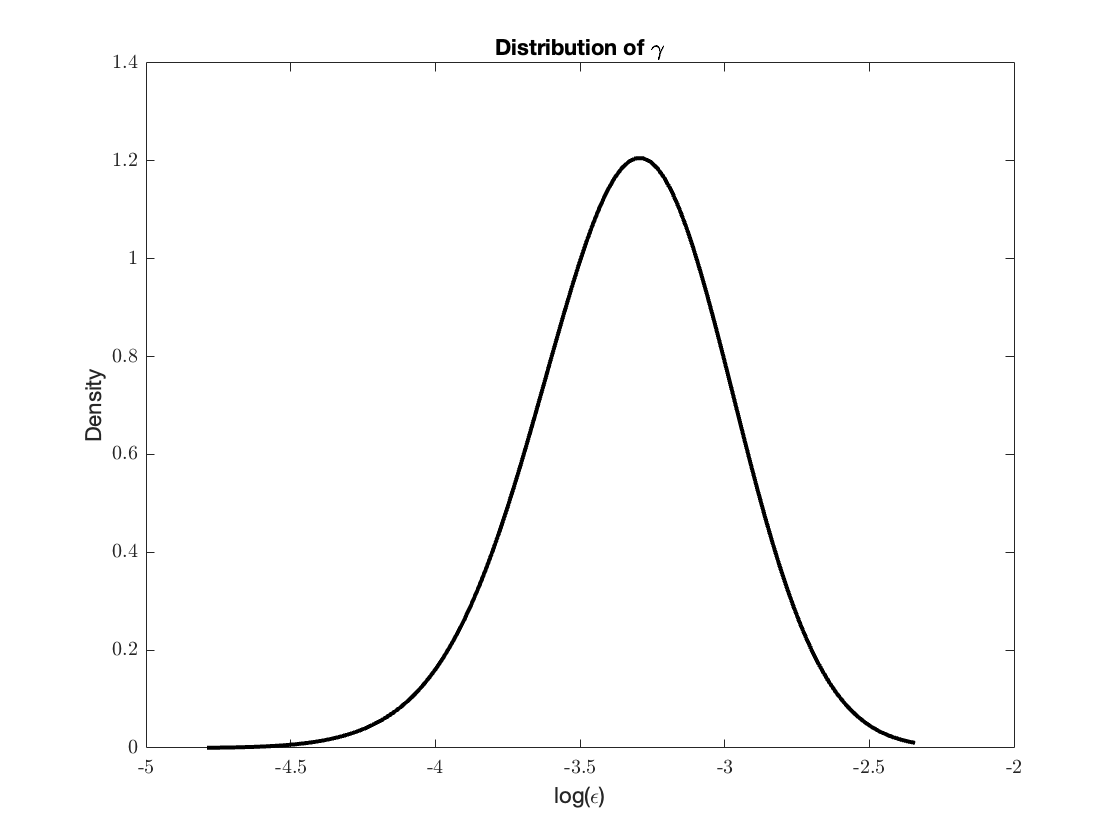


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\epsilon)');
ylabel('Density');


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_3.png','Resolution',300)

%grid
%Gamma
[f,xi] = ksdensity(log(grid(:,1)));
fprintf('\n GRID: median gamma = %.2f  ', median(grid(:,1)))


 GRID: median gamma = 0.60  

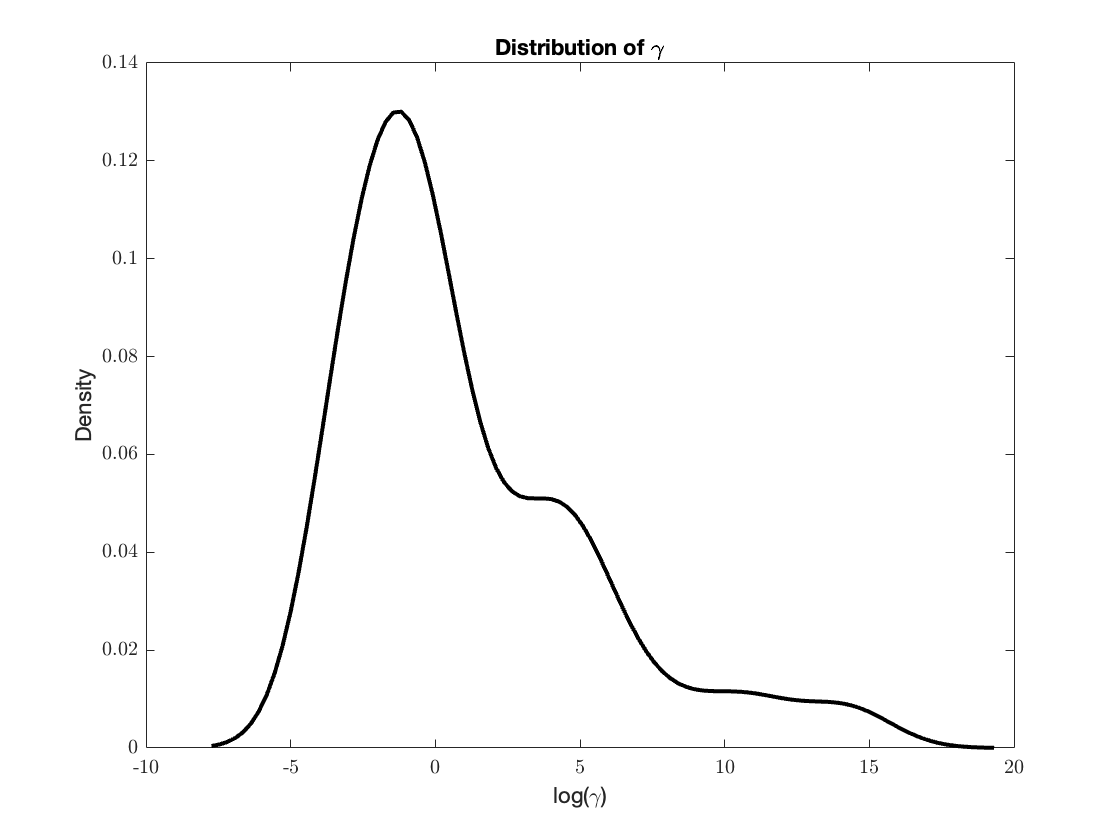



figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\gamma)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_4.png','Resolution',300)



%gird
%Sigma
[f,xi] = ksdensity(log(grid(:,2)));
fprintf('\n GRID: median sigma = %.2f  ', median(grid(:,2)))


 GRID: median sigma = 0.20  

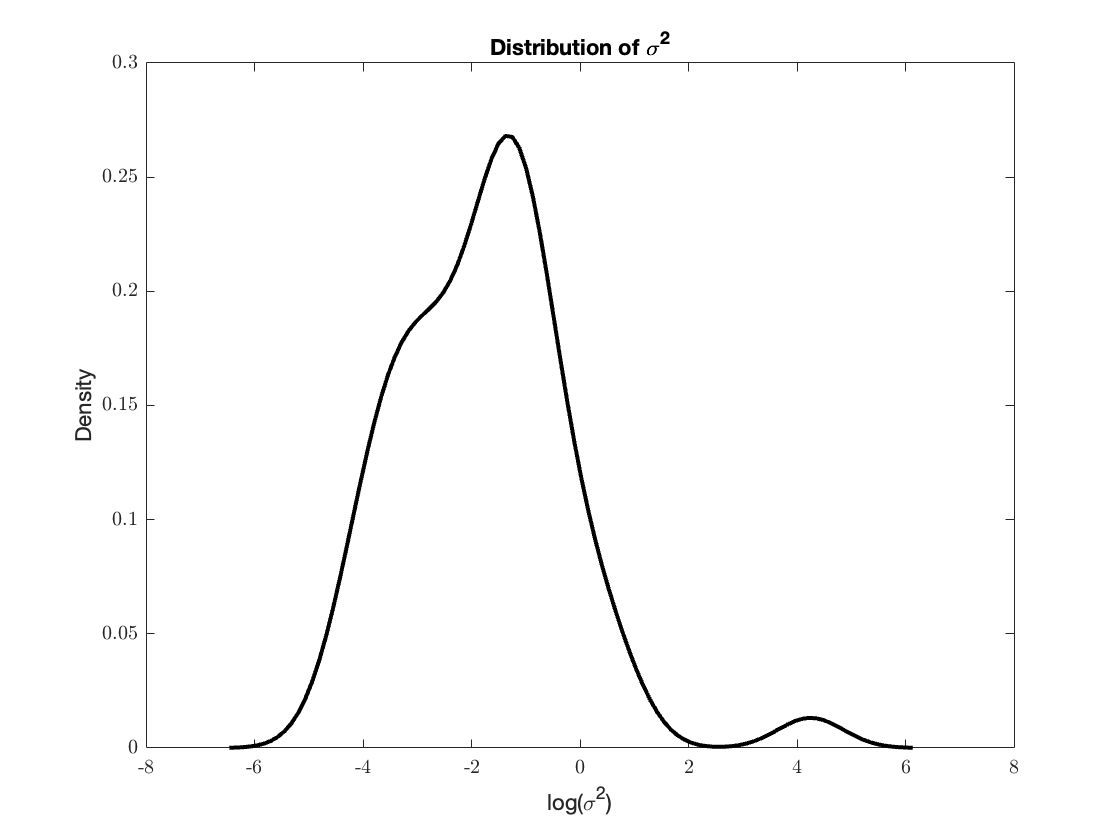


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)

title('Distribution of \sigma^2');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\sigma^2)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_5.png','Resolution',300)



%grid
%Cost (error)
[f,xi] = ksdensity(log(grid(:,3)));
fprintf('\n GRID: median cost = %.2f  ', median(grid(:,3)))


 GRID: median cost = 0.04  

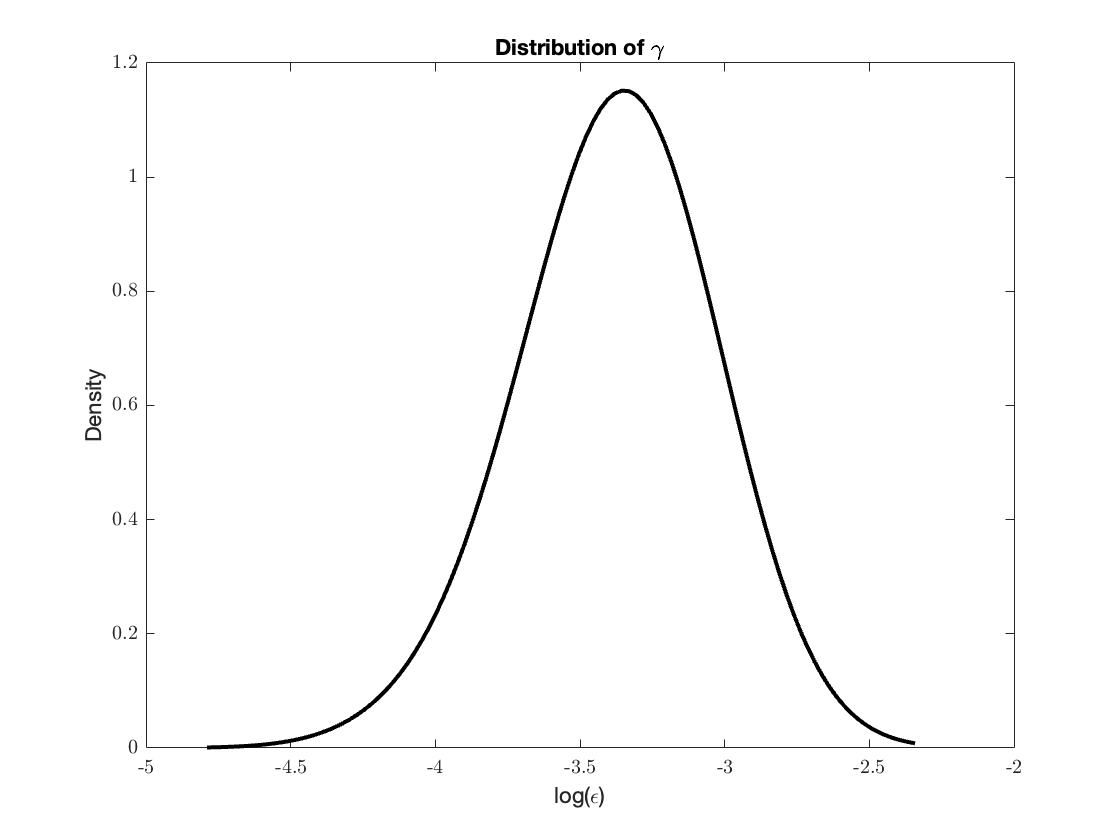


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\epsilon)');
ylabel('Density');


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_133_6.png','Resolution',300)